## Import and format constant-speed data

% Load constant speed line data
load('EFCC90_XSRANGE_speed.mat')

% Create matricies for corrected mass flow rate and pressure ratios
mdot_TLU = [Line30000(:,1)'; Line40000(:,1)'; Line50000(:,1)'; Line60000(:,1)'; Line65000(:,1)'];
pr_TLU   = [Line30000(:,2)'; Line40000(:,2)'; Line50000(:,2)'; Line60000(:,2)'; Line65000(:,2)'];

% Values taken from the constant speed lines
omega_TLU = [30000, 40000, 50000, 60000, 65000];

% Beta ranges from 0 to 1. Length = number of points taken along each constant speed line 
beta_TLU  = linspace(0,1,11);

## Import and format constant-efficiency data

% Load efficiency data
load('EFCC90_XSRANGE_efficiency.mat')

% Organize efficiency data for use in scatteredInterpolant
Efficiency50 = [Eff50, 0.50 .* ones(length(Eff50),1)];
Efficiency55 = [Eff55, 0.55 .* ones(length(Eff55),1)];
Efficiency60 = [Eff60, 0.60 .* ones(length(Eff60),1)];
Efficiency65 = [Eff65, 0.65 .* ones(length(Eff65),1)];
Efficiency70 = [Eff70, 0.70 .* ones(length(Eff70),1)];
Efficiency75 = [Eff75, 0.75 .* ones(length(Eff75),1)];

Efficiency = [Efficiency50; Efficiency55; Efficiency60; Efficiency65; Efficiency70; Efficiency75];

## Interpolation

% Interpolate efficiency data onto the corrected mass flow rate and
% pressure ratio locations - this allows the same corrected speed and beta
% values to be used for all three tables

F = scatteredInterpolant(Efficiency(:,1), Efficiency(:,2), Efficiency(:,3), 'linear', 'linear');
eta_TLU = F(mdot_TLU, pr_TLU);

## Plot compressor map

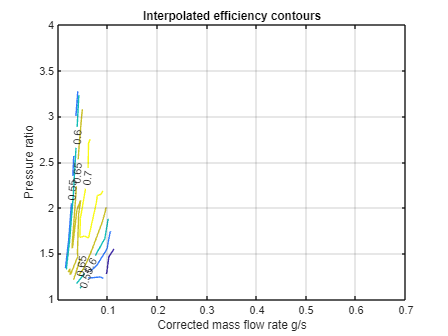

[C, h] = contour(mdot_TLU, pr_TLU, eta_TLU, 0.50:0.05:0.75);
clabel(C, h, 'LabelSpacing', 350)
h.DisplayName = 'Isentropic Efficiency';
title('Interpolated efficiency contours')
xlabel('Corrected mass flow rate g/s')
ylabel('Pressure ratio')
axis([0 0.15 1 3.5])
xticks(0.02:0.02:0.14)
grid on